# Bayesian simulation

When it is not possible to form a posterior distribution analytically, an alternative is to use a method that can draw samples from the posterior. With these samples, features of the posterior distribution such as its mean and maximum can be estimated, as well as expected values of functions over the posterior distribution.

This live script shows a method of drawing samples from the posterior distribution. The method can give you some insight into Bayesian inference. However, you will see it is not very practical (this script can take 5-10 minutes to run!). A practical method for sampling is shown in the script on Markov chain Monte Carlo methods, `mcmc`.

Consider the nonlinear model


$$f(x;w) = x - \frac{x^2}{w^2}$$


and the following 3 observations. We assume that the noise variance is 2.

x = [1 2 3]';
y = [1.4517 3.3589 -2.9723]';
sigma2 = 2;

The likelihood function is


$$\frac{1}{(2 \pi \sigma^2)^{(n/2)}} \exp \left[ -\frac{1}{2\sigma^2} \sum_{i=1}^{n} \left(x_i - \frac{x_i^2}{w^2} - y_i \right)^2 \right]$$


which, as we saw earlier, is not Gaussian.

For our Bayesian analysis to estimate the posterior distribution of $w$, let us use the prior distribution $N(1.8, 0.01)$. The posterior distribution cannot be formed analytically in this case, at least not easily. To be clear, we can form an expression for the unnormalized posterior distribution, but not the properly normalized distribution.

We will now generate and store a large number of samples from the posterior. 

num_samp = 1000;        % number of samples
c = zeros(num_samp, 1); % storage for the samples
num = 0;                % counter for the samples
tic                     % start a timer

To try to generate a sample, $w$ is first drawn from the prior. Then this $w$ is used to generate synthetic data (`ytilde)` according to our model and noise variance. If the set of synthetic data matches or is close enough to our set of observed data, then the sample $w$ is accepted and stored. Otherwise, the sample $w$ is not valid.

while (num < num_samp)
  % sample from the prior
  w = sqrt(0.1)*randn + 1.8;
  % generate synthetic data
  ytilde = x - (x/w).^2 + sqrt(sigma2)*randn(size(x));
  % if the synthetic data matches observations
  if norm(y-ytilde, Inf) < 0.1
    num = num + 1;
    % print progress
    if mod(num, 100) == 0, fprintf('Samples computed: %5d\n', num); end
    c(num) = w;
  end
end

Samples computed:   100
Samples computed:   200
Samples computed:   300
Samples computed:   400
Samples computed:   500
Samples computed:   600
Samples computed:   700
Samples computed:   800
Samples computed:   900
Samples computed:  1000


toc % stop the timer

Elapsed time is 428.529361 seconds.


The above code will take a long time to run, since it will take many trials just to find one match. To track progress, the code prints a message every time 100 samples have been generated.

Once the above code is completed, we can print a histogram of our samples.

binwidth = 0.075;
w = 1+binwidth:binwidth:2.5-binwidth;
h = hist(c, w);
clf
plot(w, h, 'rx');
hold on

We'll overlay the histogram with a plot of the unnormalized density function. To approximately normalize the density for the sake of the plot, we will scale it so that its maximum value matches the maximum value in the histogram. The analytic form of the likelihood function was worked out in the live script on nonlinear models.

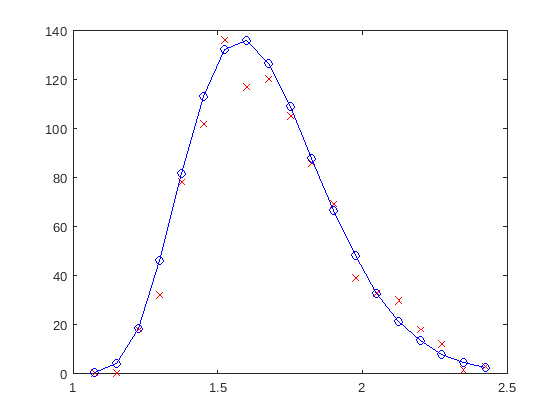

fun = @(w) exp(-0.5/sigma2 * (98./(w.^4) - 95.7259./(w.^2) + 37.7188))...
    .* pdf('Normal', w, 1.8, sqrt(0.1));
y = fun(w);
plot(w,y/max(y)*max(h),'bo-');

The histogram of the samples shows a reasonable approximation to the posterior distribution.

### Taking it further

Try using a different prior distribution. If the prior distribution is the uniform distribution between 1 and 2 (a flat or uninformative prior), what is the shape of the unnormalized posterior?

As we already mentioned, this naive form of sampling is very slow. Now take a look at the script on Markov chain Monte Carlo methods, `mcmc`, to see what is more often used in practice.